# Test DecisionTreeClass

Initialise: clear environment, load dataset class instances.

Starting decision tree analysis...
Completed decision tree analysis


    numberOfFolds    minLeafSize    minParentSize    maxNumSplit    splitCriterion    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    predictTime    randomSeed
    _____________    ___________    _____________    ___________    ______________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________    ___________    __________

          2               1          

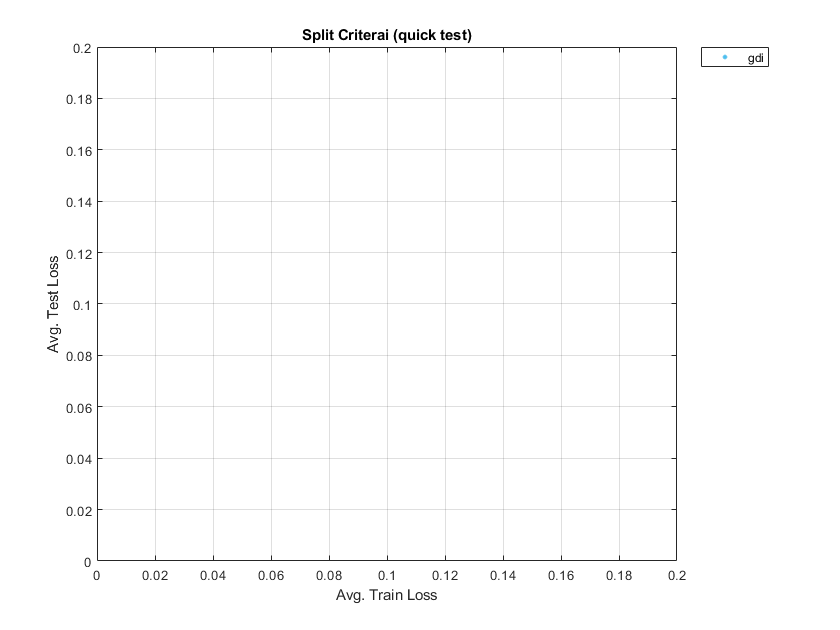

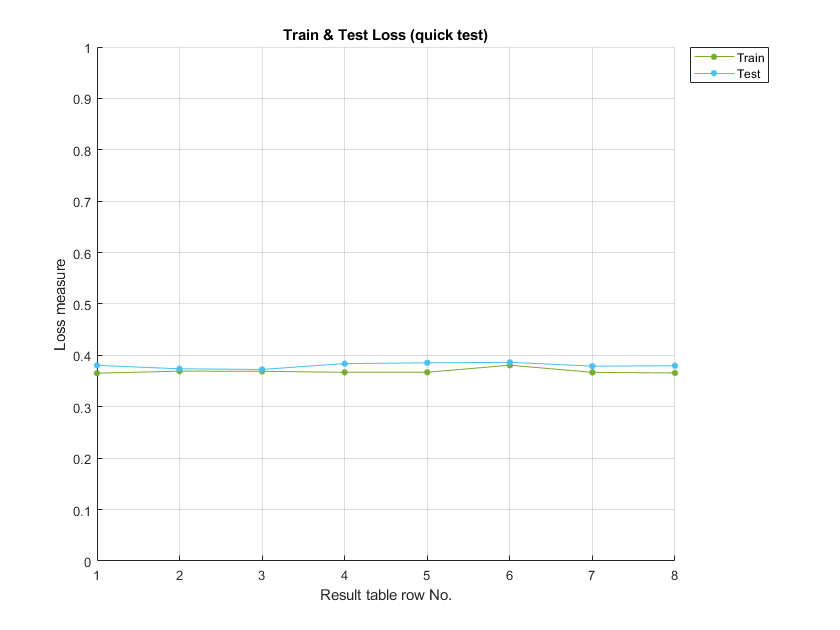

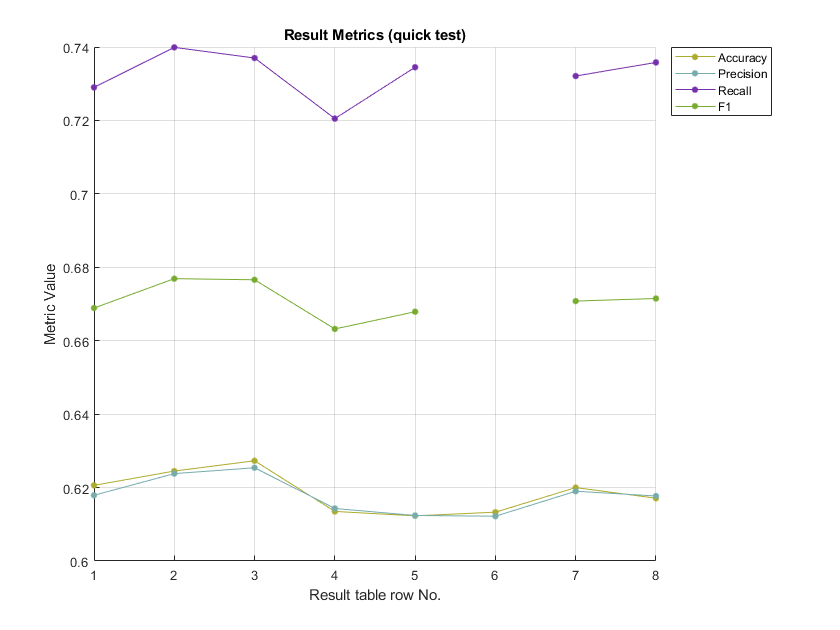

clear
clc
clf
close all
load letterDatasetClass.mat

## Run hyperparameter search on all columns, all parameters:

**letterDatasetScaled** and **letterDatasetNormalised** are used in this section.

### Perform search on scaled dataset (takes time)

treeAllFeatureResultsNotNormalised = performTreeAnalysis(letterDatasetNotNormalised, "treeAllFeatureResultsNotNormalised.csv");

Starting decision tree analysis...
Completed decision tree analysis


### Perform search on normalised dataset (takes time)

treeAllFeatureResultsNormalised = performTreeAnalysis(letterDatasetNormalised, "treeAllFeatureResultsNormalised.csv");

Starting decision tree analysis...
Completed decision tree analysis


### Display the results of test and train Loss on normalised and unnormalised

datasets: From this we can see that normalisation has no effect

#### Results of the dataset that has not been normalised

% load results from csv file:
treeAllFeatureResultsNotNormalised = LetterDecisionTreeResults.getInstanceFromCsvResults("treeAllFeatureResultsNotNormalised.csv");
% display results table
disp(treeAllFeatureResultsNotNormalised.resultsTable);

    numberOfFolds    minLeafSize    minParentSize    maxNumSplit    splitCriterion    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    predictTime    randomSeed
    _____________    ___________    _____________    ___________    ______________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________    ___________    __________

          2               1          

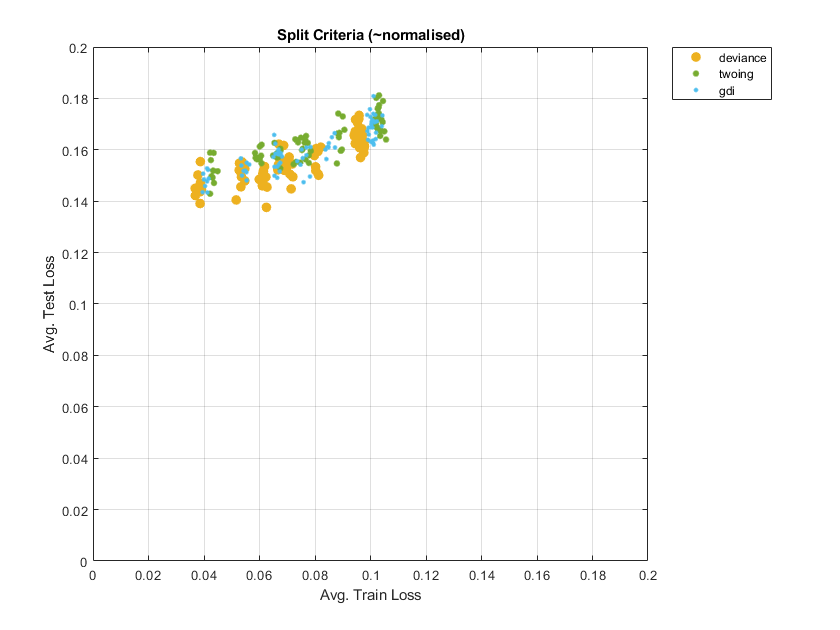

% plot split criteria comparison
treeAllFeatureResultsNotNormalised.plotCriteriaLoss("Split Criteria (~normalised)")

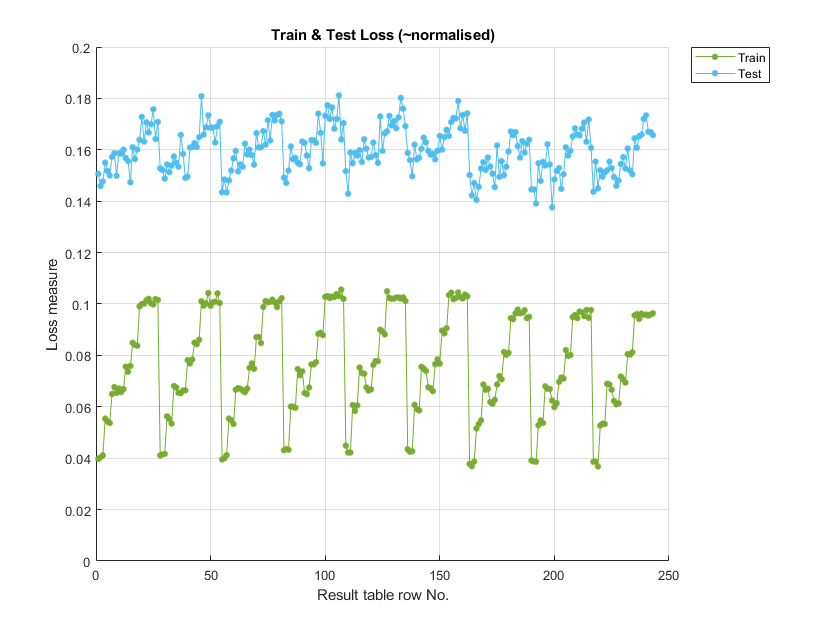

% plot test train comparison
PlotUtil.plotLossTestTrainComparisonWithYMax(treeAllFeatureResultsNotNormalised.resultsTable,...
 "Train & Test Loss (~normalised)", 0.2);

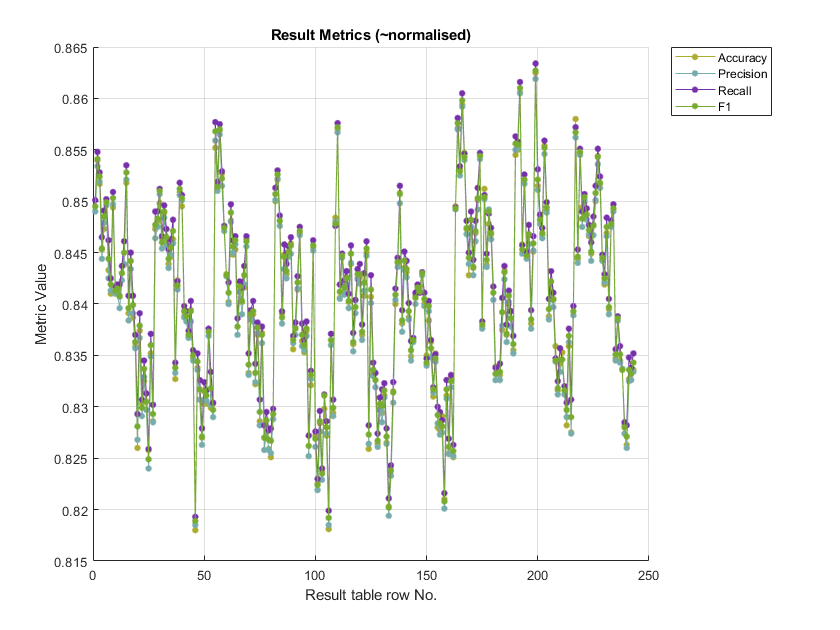

% plot metrics
PlotUtil.plotMetrics(treeAllFeatureResultsNotNormalised.resultsTable, "Result Metrics (~normalised)");

The rows that show least test loss and higher metrics are: 55, 110, 164, 166, 192, 199: The 'deviance' split criterion is slightly better.

disp(treeAllFeatureResultsNotNormalised.resultsTable([55, 110, 164, 166, 192, 199],:));

    numberOfFolds    minLeafSize    minParentSize    maxNumSplit    splitCriterion    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    predictTime    randomSeed
    _____________    ___________    _____________    ___________    ______________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________    ___________    __________

          2               1          

The test loss, accuracy, recall, precision and F1 are taken together to find the hyperparameters which have the lowest test loss and higher values for precision, recal, F1 and accuracy. The precision, recal, F1 and accuracy are alll closely grouped, this is should help achieving the goal of getting good performance.

The hyperparameters to use here are 2 folds, minLeafSize = 1, maxParentSize = 6, maxNumSplit = 8000, random seed = 192.

#### Normalised dataset results

% load results table from csv
treeAllFeatureResultsNormalised = LetterDecisionTreeResults.getInstanceFromCsvResults("treeAllFeatureResultsNormalised.csv");
% display results table
disp(treeAllFeatureResultsNormalised.resultsTable);

    numberOfFolds    minLeafSize    minParentSize    maxNumSplit    splitCriterion    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    predictTime    randomSeed
    _____________    ___________    _____________    ___________    ______________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________    ___________    __________

          2               1          

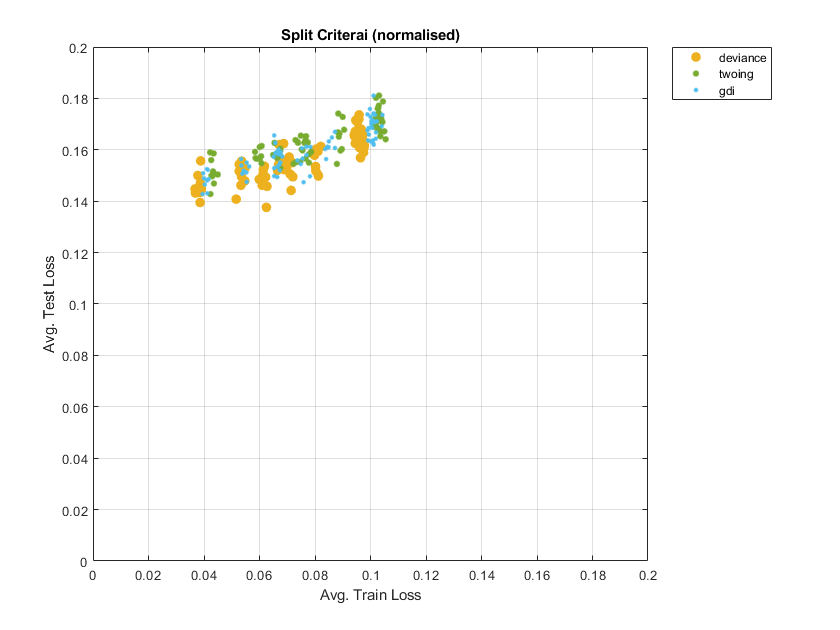

% plot split criteria comparison
treeAllFeatureResultsNormalised.plotCriteriaLoss("Split Criterai (normalised)");

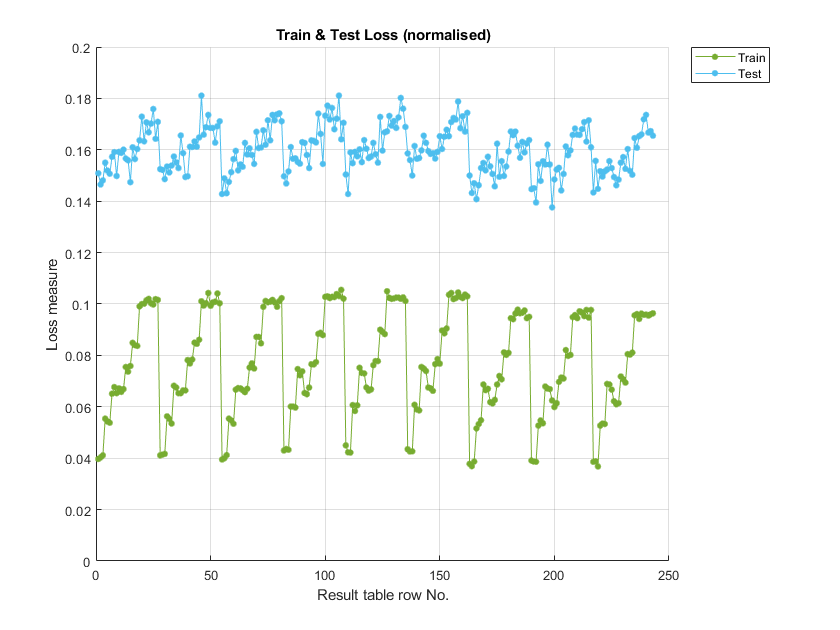

% plot train / test loss comparison
PlotUtil.plotLossTestTrainComparisonWithYMax(treeAllFeatureResultsNormalised.resultsTable,...
 "Train & Test Loss (normalised)", 0.2);

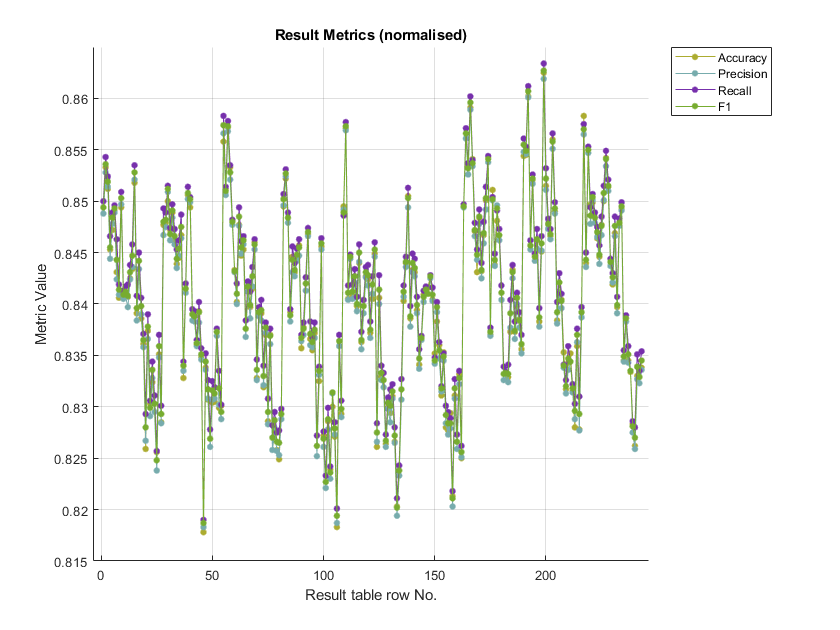

% plot metrics
PlotUtil.plotMetrics(treeAllFeatureResultsNormalised.resultsTable, "Result Metrics (normalised)");

The results for the normalised dataset are very similar to the original dataset's results.

The rows that show least test loss and higher metrics are: 55, 110, 164, 166, 192, 199:

disp(treeAllFeatureResultsNormalised.resultsTable([55, 110, 164, 166, 192, 199],:));

    numberOfFolds    minLeafSize    minParentSize    maxNumSplit    splitCriterion    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    predictTime    randomSeed
    _____________    ___________    _____________    ___________    ______________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________    ___________    __________

          2               1          

## Feature selection removing features

The same hyperparameters as in the previous test are run, this time removing features identified as good candidates for removal during the dataset analysis

The following features have been removed in the dataset:

- xBox

- yBox

- width

- height

clear
clc
clf
close all
load letterDatasetClass.mat;

### Perform hyperparameter search on dataset with features removed, and normalised (takes time)

letterDatasetNormalisedReducedFeatures is the one that is used

treeSelectedFeatureResultsNormalised = performTreeAnalysis(letterDatasetNormalisedReducedFeatures, "selectedFeatureResultsNormalised.csv");

Starting decision tree analysis...
Completed decision tree analysis


### Display of the search results: features removed, and normalised

% load results table from csv
treeSelectedFeatureResultsNormalised = LetterDecisionTreeResults.getInstanceFromCsvResults("selectedFeatureResultsNormalised.csv");
% display results table
disp(treeSelectedFeatureResultsNormalised.resultsTable);

    numberOfFolds    minLeafSize    minParentSize    maxNumSplit    splitCriterion    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    predictTime    randomSeed
    _____________    ___________    _____________    ___________    ______________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________    ___________    __________

          2               1          

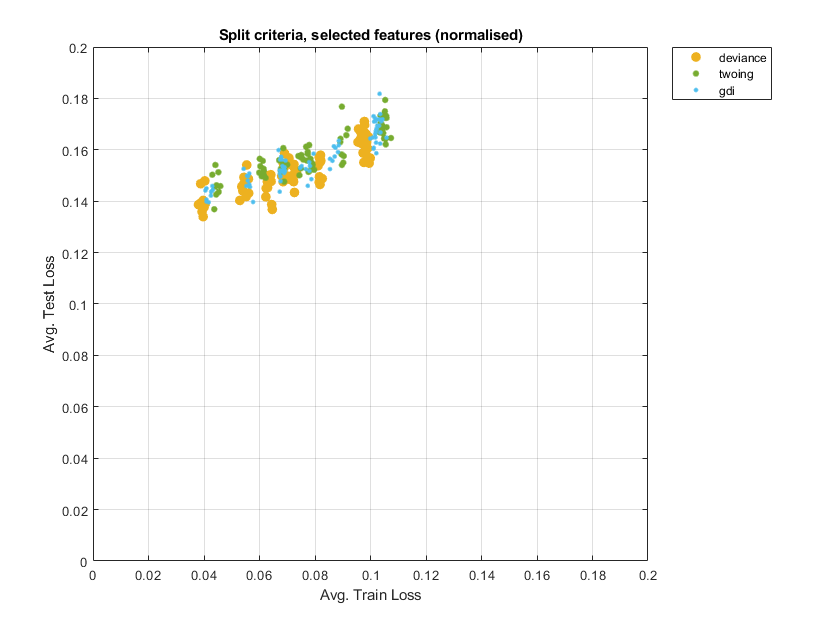

% plot split criteria comparison
treeSelectedFeatureResultsNormalised.plotCriteriaLoss("Split criteria, selected features (normalised)");

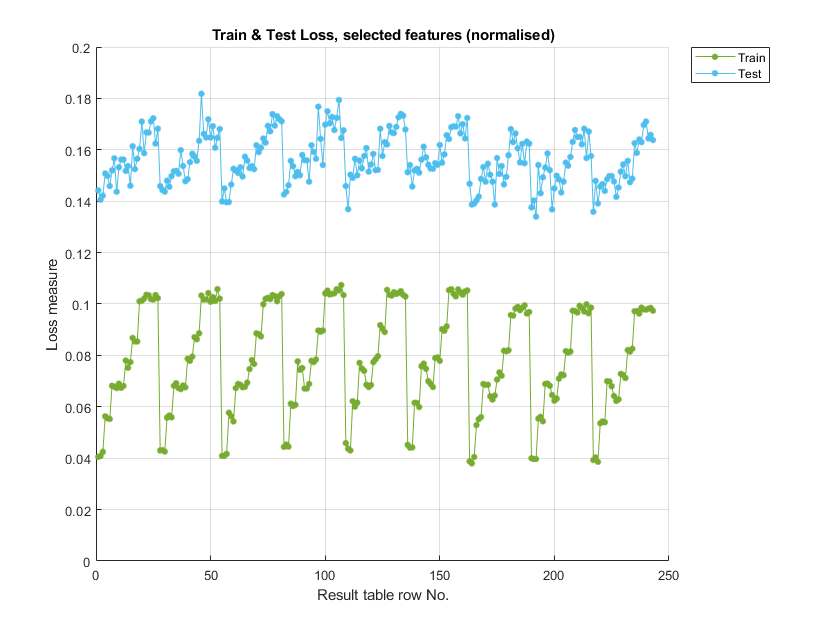

% plot train / test loss comparison
PlotUtil.plotLossTestTrainComparisonWithYMax(treeSelectedFeatureResultsNormalised.resultsTable,...
 "Train & Test Loss, selected features (normalised)", 0.2);

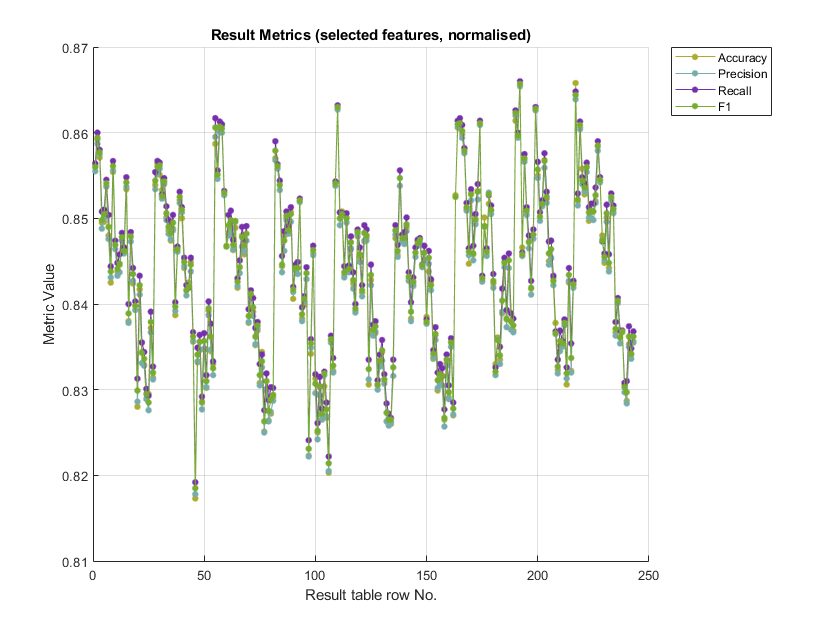

% plot metrics
PlotUtil.plotMetrics(treeSelectedFeatureResultsNormalised.resultsTable, "Result Metrics (selected features, normalised)");

 Similarly, results with good performance are on the rows 55, 110, 164, 166, 192, 199

disp(treeSelectedFeatureResultsNormalised.resultsTable([55, 110, 164, 166, 192, 199],:));

    numberOfFolds    minLeafSize    minParentSize    maxNumSplit    splitCriterion    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    predictTime    randomSeed
    _____________    ___________    _____________    ___________    ______________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________    ___________    __________

          2               1          

## Perform final test using optimal hyperparameters on complete dataset

load letterDatasetClass.mat;
finalHyperparameters = DTreeHyperparametersClass.getFinalHyperparameterInstance();
treeFinalFeatureClass = LetterDecisionTreeClass(letterDatasetNormalisedReducedFeatures);
% display info during run?
treeFinalFeatureClass.debug = false;
[treeFinalFeatureResults, treeModel, predictionResult] = treeFinalFeatureClass.performFinalDTreeHyperparameterAnalysis(finalHyperparameters, "treeFinalFeatureResults.csv");
disp(treeFinalFeatureResults.resultsTable(:,:));
% Uncomment to view the tree in a seperate window:
% view(treeModel, 'Mode', 'graph');

Starting final decision tree analysis...
Completed final decision tree analysis


When displayed in a seperate window, the tree is displayed, a depth of 19 is measured from the root node to the deepest leaf node.

[x, y] = letterDatasetNormalisedReducedFeatures.extractXYFromTable(letterDatasetNormalisedReducedFeatures.testTable);

    numberOfFolds    minLeafSize    minParentSize    maxNumSplit    splitCriterion    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    predictTime    randomSeed
    _____________    ___________    _____________    ___________    ______________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________    ___________    __________

          1               1          

yTrain = categorical(table2cell(y));
% Plot confusion matrix
matrix = confusionmat(yTrain, predictionResult);
confusionchart(matrix)

## Conclusion

Training the tree using the hyperparameters with: minLeafSize = 1, maxParentSize = 6, maxNumSplit = 8000, random seed = 192, deviance split criterion; give very good results on the hold out test set. The confusion matrix shows that the blue diagonal has a high proprtion of correct classifications. The results' average test loss of 0.1186 is also very good.

## Functions defined for the initial tests

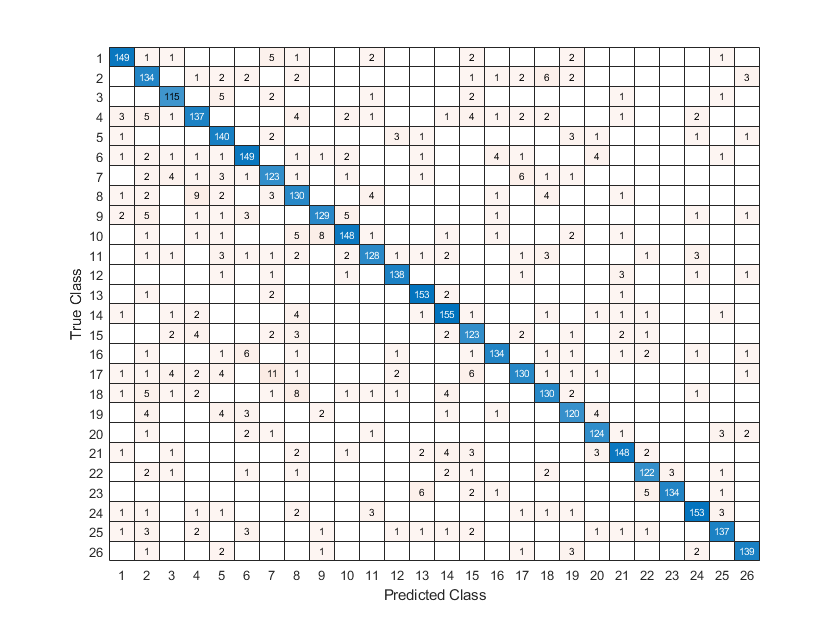

function results = performQuickTreeAnalysis(letterDataset, resultsCsvFilename)
  treeClass = LetterDecisionTreeClass(letterDataset);
  % get an initial set of hyperparameters to try, the results allow a finer
  % selection to be made later
  treeClass.debug = false;

  allFeaturesHyperparameters = DTreeHyperparametersClass.getQuickTestRunInstance();
  results = treeClass.performDTreeHyperameterAnalysis(allFeaturesHyperparameters, resultsCsvFilename);
end

Perform decision hyperparameter analysis on all features

function results = performTreeAnalysis(letterDataset, resultsCsvFilename)
  treeClass = LetterDecisionTreeClass(letterDataset);
  % get an initial set of hyperparameters to try, the results allow a finer
  % selection to be made later
  treeClass.debug = false;
  allFeaturesHyperparameters = DTreeHyperparametersClass.getInstance();
  results = treeClass.performDTreeHyperameterAnalysis(allFeaturesHyperparameters, resultsCsvFilename);
end